clear
% 1201
syms x y z;
u=2*y*sqrt(x)+3*y^2*z^(2/3)

$$u = 3\,y^{2}\,z^{2/3}+2\,\sqrt{x}\,y$$

Dux=simplify(diff(u,x))

$$Dux = \frac{y}{\sqrt{x}}$$

Duy=simplify(diff(u,y))

$$Duy = 6\,y\,z^{2/3}+2\,\sqrt{x}$$

Duz=simplify(diff(u,z))

$$Duz = \frac{2\,y^{2}}{z^{1/3}}$$

% 1202
syms x y z;
u=exp(x/y)+exp(-z/y)

$$u = {\mathrm{e}}^{x/y}+{\mathrm{e}}^{-\frac{z}{y}}$$

Dux=simplify(diff(u,x))

$$Dux = \frac{{\mathrm{e}}^{x/y}}{y}$$

Duy=simplify(diff(u,y))

$$Duy = -\frac{x\,{\mathrm{e}}^{x/y}-z\,{\mathrm{e}}^{-\frac{z}{y}}}{y^{2}}$$

Duz=simplify(diff(u,z))

$$Duz = -\frac{{\mathrm{e}}^{-\frac{z}{y}}}{y}$$

% 1203
syms x y;
z=atan(y/(1+x^2))

$$z = \mathrm{atan}\left(\frac{y}{x^{2}+1}\right)$$

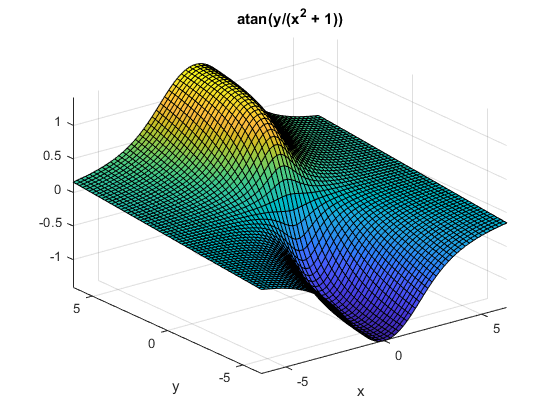

ezsurf(z)

Dzx=simplify(diff(z,x))

$$Dzx = -\frac{2\,x\,y}{x^{4}+2\,x^{2}+y^{2}+1}$$

Dzy=simplify(diff(z,y))

$$Dzy = \frac{x^{2}+1}{x^{4}+2\,x^{2}+y^{2}+1}$$

% 1204
syms x y;
z=exp((x^2+y^2)^2)

$$z = {\mathrm{e}}^{{\left(x^{2}+y^{2}\right)}^{2}}$$

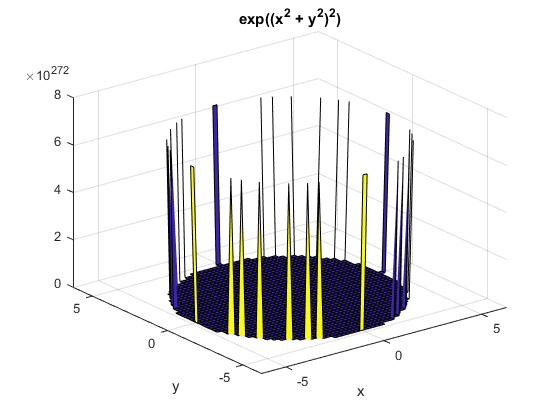

ezsurf(z)

Dzx=simplify(diff(z,x))

$$Dzx = 4\,x\,{\mathrm{e}}^{{\left(x^{2}+y^{2}\right)}^{2}}\,\left(x^{2}+y^{2}\right)$$

Dzy=simplify(diff(z,y))

$$Dzy = 4\,y\,{\mathrm{e}}^{{\left(x^{2}+y^{2}\right)}^{2}}\,\left(x^{2}+y^{2}\right)$$

% 1205
syms x y z;
u=(x-y)*(x-z)*(y-z)

$$u = \left(x-y\right)\,\left(x-z\right)\,\left(y-z\right)$$

Dux=simplify(diff(u,x))

$$Dux = -\left(y-z\right)\,\left(y-2\,x+z\right)$$

Duy=simplify(diff(u,y))

$$Duy = \left(x-z\right)\,\left(x-2\,y+z\right)$$

Duz=simplify(diff(u,z))

$$Duz = -\left(x-y\right)\,\left(x+y-2\,z\right)$$

% 1206
syms x y;
u=exp(3*x^2+2*y^2-x*y)

$$u = {\mathrm{e}}^{3\,x^{2}-x\,y+2\,y^{2}}$$

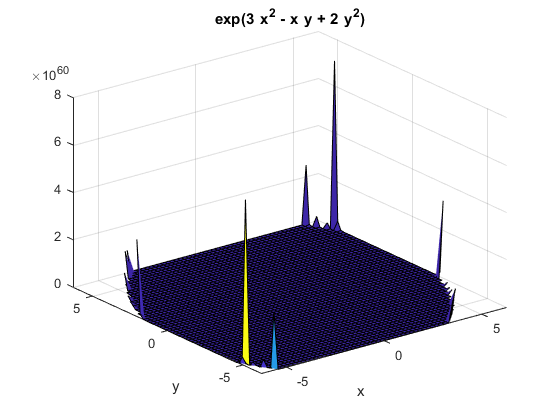

ezsurf(u)

Dux=simplify(diff(u,x))

$$Dux = {\mathrm{e}}^{3\,x^{2}-x\,y+2\,y^{2}}\,\left(6\,x-y\right)$$

Duy=simplify(diff(u,y))

$$Duy = -{\mathrm{e}}^{3\,x^{2}-x\,y+2\,y^{2}}\,\left(x-4\,y\right)$$

% 1207
syms x y z;
u=exp(x*y*z)*sin(y/x)

$$u = \sin\left(\frac{y}{x}\right)\,{\mathrm{e}}^{x\,y\,z}$$

Dux=simplify(diff(u,x))

$$Dux = -\frac{y\,{\mathrm{e}}^{x\,y\,z}\,\left(\cos\left(\frac{y}{x}\right)-x^{2}\,z\,\sin\left(\frac{y}{x}\right)\right)}{x^{2}}$$

Duy=simplify(diff(u,y))

$$Duy = \frac{{\mathrm{e}}^{x\,y\,z}\,\left(\cos\left(\frac{y}{x}\right)+x^{2}\,z\,\sin\left(\frac{y}{x}\right)\right)}{x}$$

Duz=simplify(diff(u,z))

$$Duz = x\,y\,\sin\left(\frac{y}{x}\right)\,{\mathrm{e}}^{x\,y\,z}$$

% 1208
syms x y;
z=x^2/(2*y)+x/2+1/x-1/y

$$z = \frac{x}{2}+\frac{x^{2}}{2\,y}+\frac{1}{x}-\frac{1}{y}$$

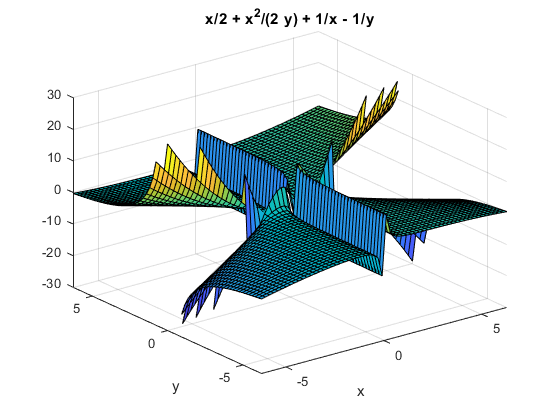

ezsurf(z)

Dzx=simplify(diff(z,x))

$$Dzx = \frac{x}{y}-\frac{1}{x^{2}}+\frac{1}{2}$$

Dzy=simplify(diff(z,y))

$$Dzy = -\frac{x^{2}-2}{2\,y^{2}}$$

e1=simplify(x^2*Dzx+y^2*Dzy)

$$e1 = \frac{x^{3}}{y}$$

e2=x^3/y

$$e2 = \frac{x^{3}}{y}$$

% 1209
syms rho theta;
x=rho*cos(theta)

$$x = \rho \,\cos\left(\theta \right)$$

y=rho*sin(theta)

$$y = \rho \,\sin\left(\theta \right)$$

A=[diff(x,rho) diff(x,theta); diff(y,rho) diff(y,theta)]

$$A = \left(\begin{array}{cc} \cos\left(\theta \right) & -\rho \,\sin\left(\theta \right)\\ \sin\left(\theta \right) & \rho \,\cos\left(\theta \right) \end{array}\right)$$

simplify(det(A))

$$ans = \rho$$